idx1 = 1×488 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


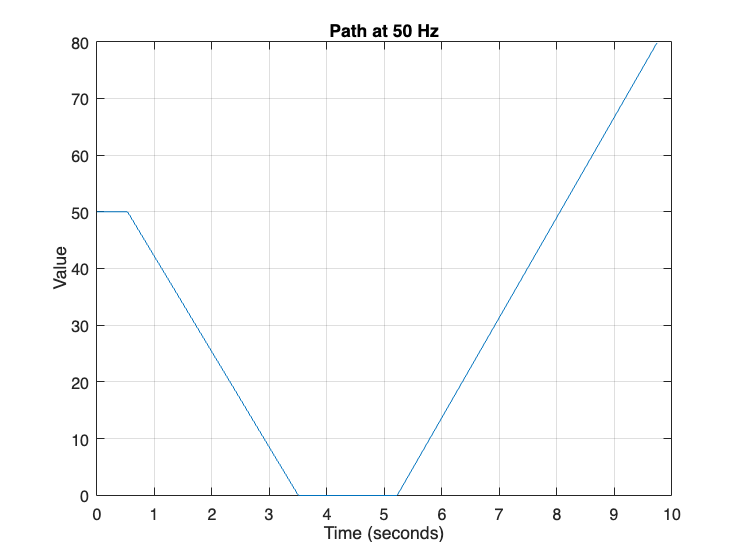

fs = 50; 

total_time = 9.7551; 
t1 = 0.5365;
t2 = 3.506;
t3 = 5.225;
t4 = 9.7551;
t = 0:1/fs:total_time;
path = zeros(size(t));
idx1 = t <= t1
path(idx1) = 50;
idx2 = t > t1 & t <= t2;
path(idx2) = 50 * (1 - (t(idx2) - t1) / (t2 - t1));
idx3 = t > t2 & t <= t3;
path(idx3) = 0;
idx4 = t > t3 & t <= t4;
path(idx4) = 80 * (t(idx4) - t3) / (t4 - t3);

